# Equations of Motion

6-DOF equations of motion are composed of or 3 translational equations of motion, and 3 angular equations of motion.  We represent these equations as:


$$^BF = m.(\enspace ^B\dot{v}  \enspace + \enspace
{^B\omega} \times {^Bv} \enspace)$$



$$^BM = {^BI}. ^B\dot{\omega}  \enspace + \enspace
{^B\omega} \times ({^BI \thinspace. \thinspace ^B\omega}) \enspace$$


where $^BX$ means that the components of $X$ are expressed in the vehicles body fixed frame.  To convert the body rates $^B\omega$ into Euler rates we'll use the following rotation sequence:

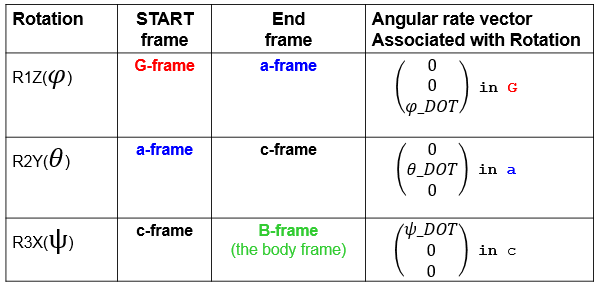

NOTE: a slightly more descriptive and verbose nomenclature for our 6-DOF equations of motion would be the following:


$$^BF = m.(\enspace ^B_-\dot{v}_C  \enspace + \enspace
{^B_G\omega_B} \times {^B_Gv_C} \enspace)$$



$$^BM = {^BI} \thinspace . ^B_-\dot{\omega}_B  \enspace + \enspace
{^B_G\omega_B} \times ({^BI \thinspace. \thinspace ^B_G\omega_B}) \enspace$$


where:

$\matrix{

\bullet & {^B_Gv_C}  
}$    :    A vector representing the vehicles ***velocity*** of the  centre of mass C.  The vector is expressed in components of the B-frame.  The G subscript indicates that the "measurement" of the velocity is as seen by the G-frame. 

$\matrix{
\bullet & ^B_-\dot{v}_C = \enspace 
_B\pmatrix{
\frac{d \enspace ^B_Gv_C}{dt}
}
}$    :    the derivative of $^B_Gv_C$ as seen by the B-frame, and expressed in components of the B-frame.  So if we integrate $^B_-\dot{v}_C$, then we'll get $^B_Gv_C$.

$\matrix{

\bullet & {^B_G\omega_B}  
}$   :    the angular ***velocity*** of the B-frame as observed by the G-frame, and expressed in components of the B-frame.

$\matrix{
\bullet & {^B_-\dot{\omega}_B}  = \enspace

_B\pmatrix{
\frac{d \enspace ^B_G{\omega}_B}{dt}
}
}
}$   :    the derivative of  $\matrix{
{^B_G{\omega}_B}  
}$  as seen by the B-frame, and expressed in components of the B-frame.  So if we integrate $\matrix{

{^B_-\dot{\omega}_B}  
}$, then we'll get $\matrix{
{^B_G{\omega}_B}  
}$.

$\matrix{

\bullet & {^BI}  
}$      :    the Inertia of the body computed about the B-frame which is attached to the body's center of mass.

$\matrix{

\bullet 
}$    *B-frame*  :    the body fixed frame attached to the body's center of mass.

$\matrix{

\bullet 
}$    G*-frame*  :   the inertial reference frame.

$\matrix{

\bullet 
}$    A . B  :   matrix A multiplied by matrix B.

$\matrix{

\bullet & a \times b
}$    :   vector CROSS product.

## **Define vehicle Mass, Inertia and Initial Conditions**

I = [ ...
            0.005831943165131, 0,                 0;
            0,                 0.005831943165131, 0;
            0,                 0,                 0.011188595733333;
          ]; % (kg.m^2)
       
m  = 0.9272;    % (kg)
g = 9.81;
% Vehicle INITIAL conditions 
Vb_init     = [0;0;0]; % (m/sec)    Initial velocity in BODY axes
wb_init     = [0;0;0]; % (rad/sec)  Initial body rates
eul_init    = [0;0;0]; % (rad)      Initial EULER angles [yaw,pitch,roll]
Xe_init     = [0;0;0]; % (m)        Initial position in INERTIAl axes

% state vector INITIAL conditions
q_init = [ Vb_init;
           wb_init;
           eul_init;
           Xe_init   ];

## define the ODE system to solve

we need to write a MATLAB function that defines the "state derivatives" of the system of interest.  ie:  I need to write a MATLAB function that represents a general system:


$$\dot{\matrix{q}} = f(t,q)$$


For our system we're going to define the following 12 element state vector $\bf{q}$ and the corresponsing 12 element vector of state derivatives $\bf {\dot{q}}$:

- $\bf{q}$ = $\pmatrix{
\enspace ^Bv_x \enspace , 
\enspace ^Bv_y \enspace , 
\enspace ^Bv_z \enspace ,
\enspace ^B\omega_x \enspace ,
\enspace ^B\omega_y \enspace ,
\enspace ^B\omega_z \enspace ,
\enspace \phi \enspace ,
\enspace \theta \enspace ,
\enspace \psi \enspace ,
\enspace ^GX \enspace , 
\enspace ^GY \enspace , 
\enspace ^GZ \enspace  
}$

- $\bf {\dot{q}}$ = $\pmatrix{
\enspace ^B\dot{v}_x \enspace , 
\enspace ^B\dot{v}_y \enspace , 
\enspace ^B\dot{v}_z \enspace ,
\enspace ^B\dot{\omega}_x \enspace ,
\enspace ^B\dot{\omega}_y \enspace ,
\enspace ^B\dot{\omega}_z \enspace ,
\enspace \dot{\phi} \enspace ,
\enspace \dot{\theta} \enspace ,
\enspace \dot{\matrix{\psi}} \enspace ,
\enspace ^G\dot{X} \enspace , 
\enspace ^G\dot{Y} \enspace , 
\enspace ^G\dot{Z} \enspace  
}$

% Define Excitation Forces and Moments (in BODY frame)
% simulate free fall assuming Z-axis is pointing down (NED)
Fb = zeros(3,1);
Mb = zeros(3,1);
Fb(3)=9.8*m; % due to gravity
Fb_and_Mb = [ Fb;
              Mb ];   
FM_at_t   = @(t)(Fb_and_Mb);

% define the system that we want to solve
dqdt_at_t = @(t, q) quad_6dof_eoms( t, q, m, I, FM_at_t );

% Define some ODE solver settings
t_span     = [0 5];   % (sec), [tstart, tend]
my_options = odeset('RelTol', 1e-7, 'AbsTol', 1e-7);

% OK: let's use  ODE solver
[T, Q]  = ode45(dqdt_at_t, t_span, q_init, my_options);

Plot the solution:

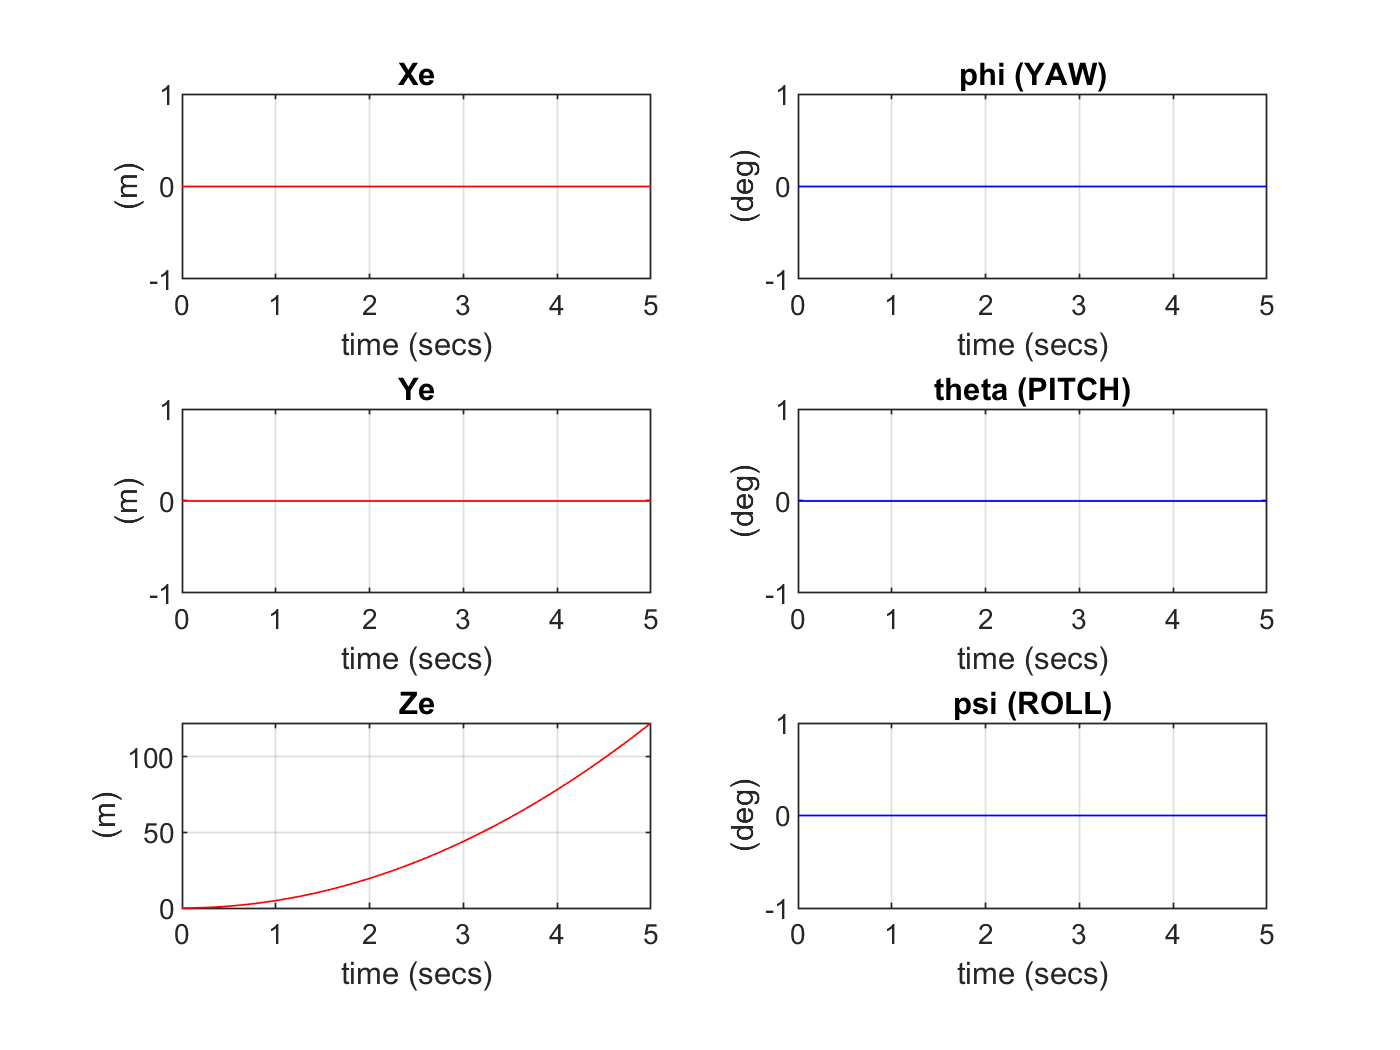

% plot our solution
figure;  plot_pose(T, Q)

# Simulink simulation

The equations can be implemented in Simulink the same way.

open_system("quad_eom.slx");
sim('quad_eom.slx',5);

## `References`

`Bradley Horton : 01-Mar-2016, bradley.horton@mathworks.com.au`